# AUTOREGRESSIVE INTEGRATED MOVING AVERAGE (ARIMA) TO FORECAST STOCK PRICE

Kevin Chng

kevin.chng@techsource-asia.com / kevinchng@hotmail.com

Application Engineer, TechSource System Pte Ltd

## Overview :

In this script, it use ARIMA model in MATLAB to forecast Stock Price. Using real life data, it will explore how to manage time-stamped data and tune the parameters of ARIMA Model (Degree of Integration, Autoregressive Order, Moving Average Order) . Prior to ARIMA model, it requires to perform exploratory data analysis and transform the data into stationary data. It also recommend what are the important indicators to looking at when conducting goodness-of-fit checks. It will forecast the Stock price and run them under Monte Carlo Simulation.

[Note : Not advocating any particular strategy, factors or methodology]

## **Highlights : **

- Handling downloaded data from Yahoo Finance using the timetable object

- Transform data into stationary data with helps of exploratory data analysis

- ARIMA modelling

- Forecasting

## **Product Focus :**

- MATLAB

- Econometric Toolbox

## **Flow of Script : **

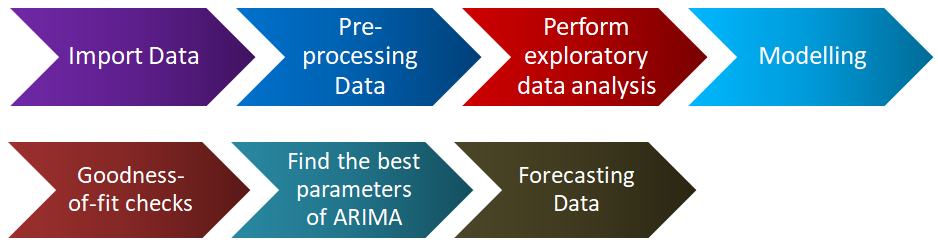

**Written at 17 August 2018**

## Load the downloaded Yahoo Finance Singapore Airline Stock Price & Pre-processing them

In this part, I downloaded the stock data of Air Asia Airlines from Yahoo Finance in excel format. Subsequently, I import it into MATLAB through command readtable(), however, take notes that the imported data is in correct data type in MATLAB. Year 2016 will be used as in-sample data to train ARIMA model.

Other than importing your excel data, there are datafeed toolbox and database toolbox allowing users to fetching data from various financial data platform (Bloomberg, Reuters, Thomson,Havar Analytica and etc) and various database platform (Ms. Access, SQL, SQLite and etc).

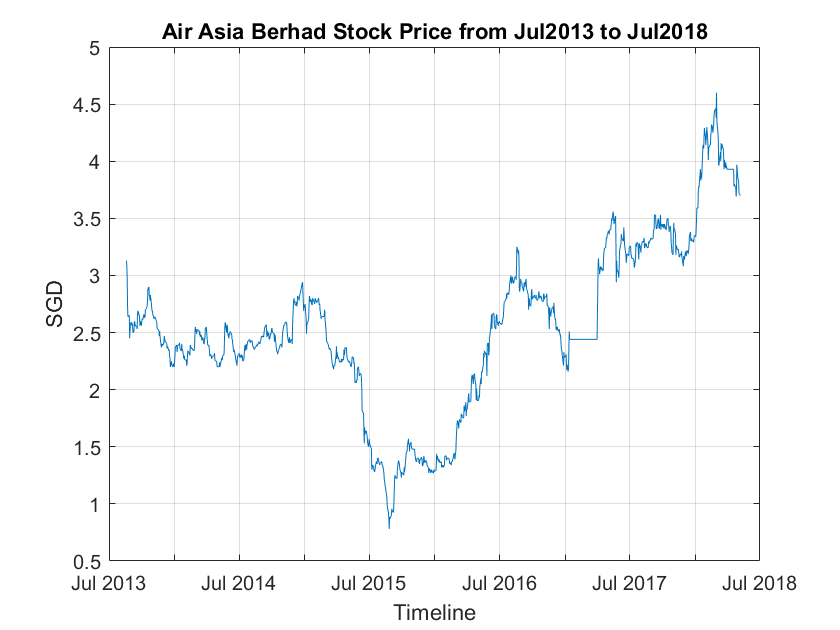

warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames');
% read data from excel 5099.KL
StockData = readtable('5099.KL.csv','ReadVariableNames',true);

%Ensure the data is in correct data type
if isnumeric(StockData.Open) == false
    Open =cellfun(@str2double,StockData.Open);
    High = cellfun(@str2double,StockData.High);
    Low = cellfun(@str2double,StockData.Low);
    Close = cellfun(@str2double,StockData.Close);
    AdjustedClose = cellfun(@str2double,StockData.AdjClose);
    Volume = cellfun(@str2double,StockData.Volume);
else
    Open = StockData.Open;
    High = StockData.High;
    Low = StockData.Low;
    Close = StockData.Close;
    AdjustedClose = StockData.AdjClose;
    Volume =  StockData.Volume;
end
Date = StockData.Date;

%Tranform the data to timetable
StockData_TimeTable = timetable(Date,Open,High,Low,Close,Volume);

%Check for missing Data
%Fill the missing data with previous value
if any(any(ismissing(StockData_TimeTable)))==true
    StockData_TimeTable = fillmissing(StockData_TimeTable,'previous');
end

%View the data
plot(StockData_TimeTable.Date,StockData_TimeTable.Close);
title('Air Asia Berhad Stock Price from Jul2013 to Jul2018');
ylabel('SGD');
xlabel('Timeline');
grid on

% get Year 2016 data out
tr = timerange('2016-01-01' , '2016-12-31');
StockData_TimeTable_2016 = StockData_TimeTable(StockData_TimeTable.Date(tr),:)

StockData_TimeTable_2016 = 250×5 timetable
       Date       Open    High    Low     Close      Volume  
    __________    ____    ____    ____    _____    __________

    2016-01-04    1.28     1.3    1.27    1.29     9.6291e+06
    2016-01-05    1.28    1.34    1.28    1.34     1.6264e+07
    2016-01-06    1.33    1.45    1.32    1.44     3.0823e+07
    2016-01-07    1.44    1.44    1.35    1.39     3.9954e+07
    2016-01-08    1.37    1.42    1.37    1.42     2.8146e+07
    2016-01-11    1.41    1.41    1.36    1.37     1.1147e+07
    2016-01-12    1.37     1.4    1.37    1.38     1.3712e+07
    2016-01-13    1.39    1.41    1.38    1.39     1.1986e

% clear unwanted variables
clear ('Open','Close','Date','AdjustedClose','High','Low','Volume','tr','StockData');

## Perform Exploratory Data Analysis And Tranform to Stationary Data

From this part onwards, we may use Econometric Modeller App to perform exploratory data analysis, tranform data into stationary data, train ARIMA model, and conduct fit-of-goodness checks.

Perform exploratory data analysis to analyze in-sample data to get some insight of parameters to transform it to stationary data and parameters of ARIMA Model.

This part also demonstrate the recommended step to do exploratory data analysis and explain what are the insight getting from the analysis. 

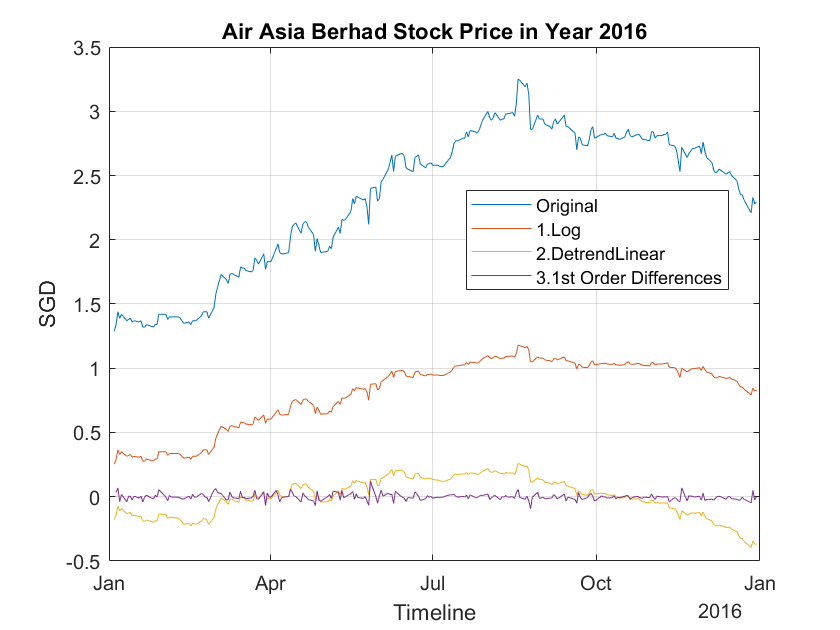

% Transform Data into Stationary Data

% Log
StockData_TimeTable_2016.CloseLog = log(StockData_TimeTable_2016.Close);

% Remove Linear trend
StockData_TimeTable_2016.CloseLogLinear = detrend(StockData_TimeTable_2016.CloseLog);

%Perform Differences
CloseLogLinearDifferences = diff(StockData_TimeTable_2016.CloseLogLinear);

%View the data
figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.CloseLog);
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.CloseLogLinear);
plot(StockData_TimeTable_2016.Date(2:end),CloseLogLinearDifferences);
title('Air Asia Berhad Stock Price in Year 2016');
ylabel('SGD');
xlabel('Timeline');
legend('Original','1.Log','2.DetrendLinear','3.1st Order Differences','Location','best')
grid on
hold off

% Test Stationary
% Hypothesis test : Augmented Dickey-filer, KPSS, Leybourne-McCabe, Philip-Peron, Variance Ratio
% Hypothesis test : Egale's ARCH, Ljung-Box Q-test
[h,p] = adftest(CloseLogLinearDifferences);
% if test is valid, it will return 1 or else 0
% P-Value will also verify the stationarity of data, It may get extremely low if your data is not valid.
display(h)

h = logical
   1


% However, in order to make our analysis easier, I recommend to try to direct apply difference techniques to the data, and check the hypothesis test
% if hypothesis test is accepted, then we should go for this way as not make our analysis complicated and have strsight-forward view
CloseDiff = diff(StockData_TimeTable_2016.Close);
[h,p] = adftest(CloseDiff);
display(h)

h = logical
   1


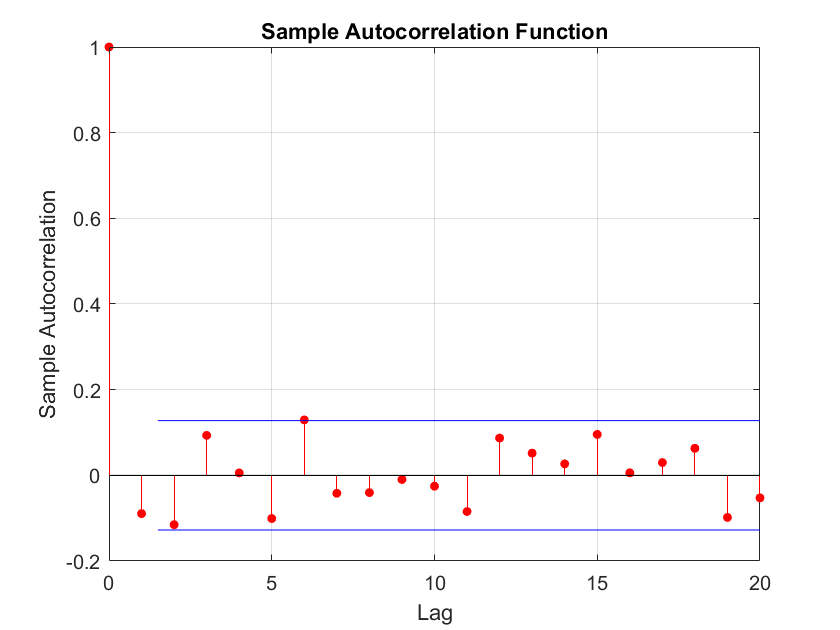


% Autocorrelaton function (ACF)
% Identify series with serial correlation
% Determine whether an AR model is apprpriate
% Identify significant MA lags for model identification

figure
autocorr(CloseDiff,'NumLags',20,'NumMA',1)

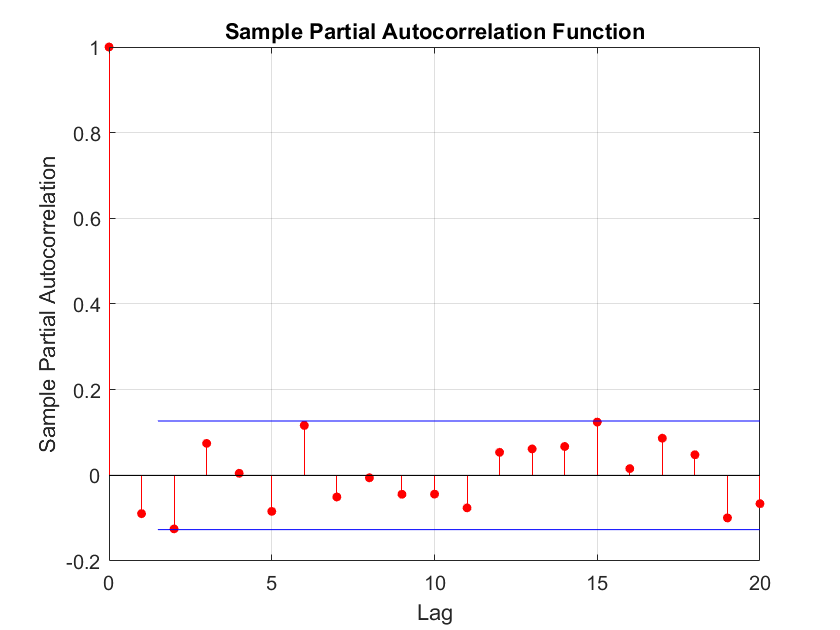

% Partial ACF (PACF)
% Identify Series with Serial Correlation
% Determine whether an MA model is appropriate
% Identify significant AR lags for model identification.
parcorr(CloseDiff,'NumAR',1,'NumLags',20);

% Do not observed obvious seosanal trend from auto-correlogram and partial-correlogram.

From the analysis above, 1st Order of differencing is sufficient to transform the model into stationary as required for ARIMA model which the conditional mean and variance are constant.

However, for ACF & Partial ACF, they are indicating that the auto-correlation is highest at 0 lag spike and clear cut at 1st lag. In this case, theoretically, we should use AR(0) and MA(0) after differencing the data. Other than this, the cylinical trend also prove the data is stationary.

## ARIMA Modelling

However, if you suspect your data has seasonal pattern, highly recommend to use SARIMA to factor the seasonal trend into the modeling.

The arima model syntax in MATLAB is ARIMA (p,D,q). 

P is autoregressive term,

D is number of non-seasonal differences,

q is moving average term

In ARIMA modelling, you consider to add your constant into modeling, else it will ignore the initial constant value.

% In our explortory data analysis, it recommend to use ARIMA(0,1,0)
ARIMA_Close = arima(0,1,0);
[ARIMA_Close1,~,Loglikehood] = estimate(ARIMA_Close,StockData_TimeTable_2016.Close)

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0039526      0.0037197        1.0626         0.28797
    Variance    0.0034306     0.00018504         18.54      9.8318e-77



ARIMA_Close1 =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: 0.00395256
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.00343058

Loglikehood = 354.6433

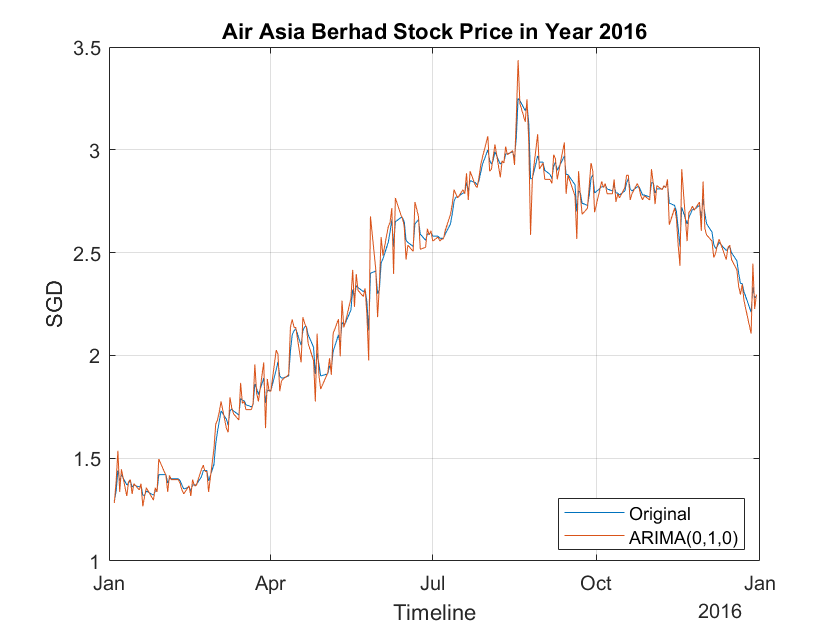

rng(1); % For reproducibility

%View the predictive vallue
residual = infer(ARIMA_Close1,StockData_TimeTable_2016.Close);
prediction = StockData_TimeTable_2016.Close + residual;

figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
plot(StockData_TimeTable_2016.Date,prediction);
title('Air Asia Berhad Stock Price in Year 2016');
ylabel('SGD');
xlabel('Timeline');
legend('Original','ARIMA(0,1,0)','Location','best');
grid on
hold off

## Goodness-of-Fit Checks

Various techniques can be used to check the fitness of regression. However, Alaike or Bayesoan information criteria is one of the popular techniques to avoid the fitting is over-fit.

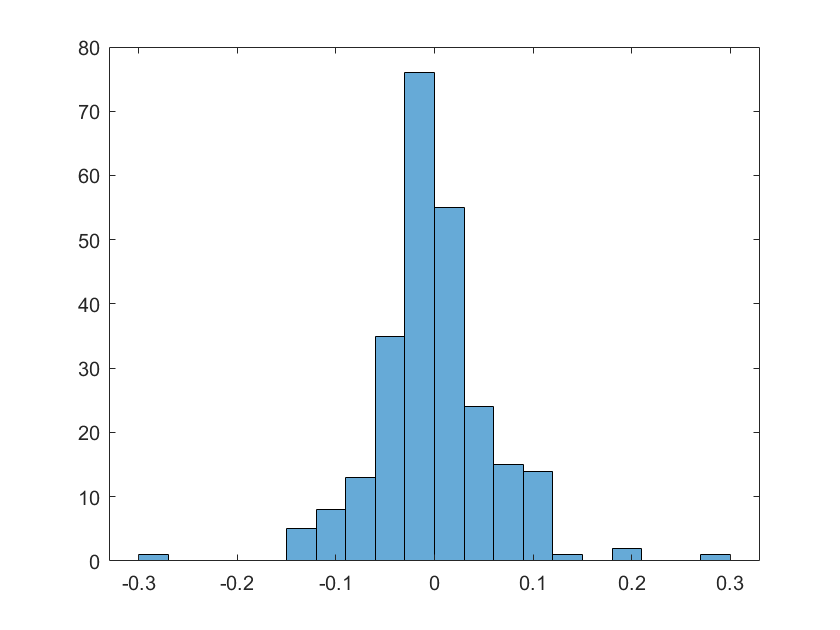

% View Resdsidual Historgram
histogram(residual)

[aic,bic] = aicbic(Loglikehood,2,250)

aic = -705.2865

bic = -698.2436

## **Find the best fit model of ARIMA**

Althought in the exploratory analysis indicating that ARIMA(0,1,0) is the best model, however, it is always good to compare the fitness of various model in case that explatory analysis does not give accurate result.

Name = "Arima(0,1,0)";
AIC = aic;
BIC = bic;

W=2;
for i = 1:2
    for j = 1:2
        for k=1:2
            ARIMA_CloseE(W-1) = arima(i,j,k);
            [~,~,LoglikehoodE] = estimate(ARIMA_CloseE(W-1),StockData_TimeTable_2016.Close,'display','off');
            [aicE,bicE] = aicbic(LoglikehoodE,2,250);
            a=convertCharsToStrings(strcat('Arima(',num2str(i),',',num2str(j),',',num2str(k),')'));
            Name(W) = a;
            AIC(W) = aicE;
            BIC(W) = bicE;
            W=W+1;
        end
    end
end

TableComparison = table;
TableComparison = table(Name',AIC',BIC')

TableComparison = 9×3 table
         Var1          Var2       Var3  
    ______________    _______    _______

    "Arima(0,1,0)"    -705.29    -698.24
    "Arima(1,1,1)"     -708.7    -701.65
    "Arima(1,1,2)"    -711.07    -704.03
    "Arima(1,2,1)"    -697.76    -690.72
    "Arima(1,2,2)"    -715.44    -708.39
    "Arima(2,1,1)"    -711.87    -704.83
    "Arima(2,1,2)"    -716.36    -709.32
    "Arima(2,2,1)"    -707.92    -700.88
    "Arima(2,2,2)"    -715.94     -708.9


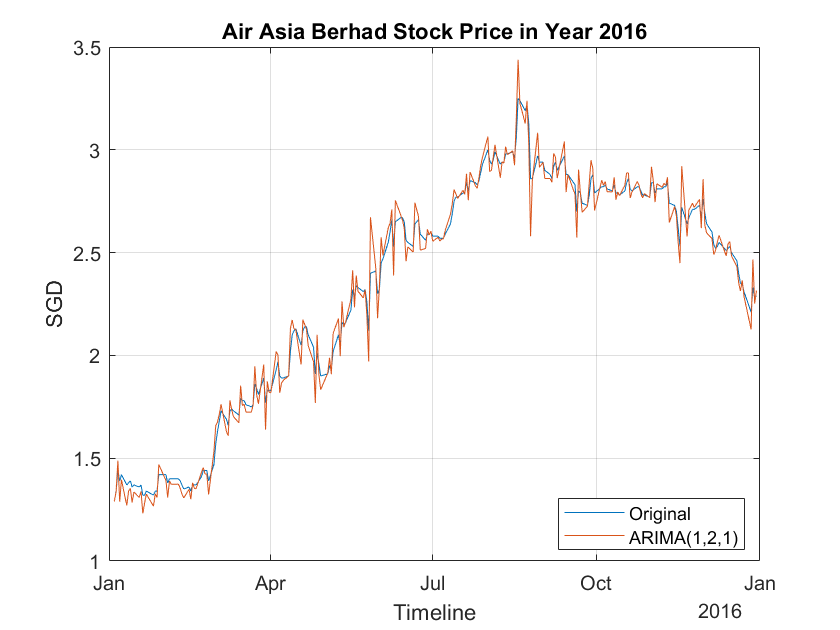

TableComparison.Properties.VariableNames = {'NameModel','AIC','BIC'};
%find the lowest AIC and BIC
AICWin = AIC(1);
recordAIC = i;
%Lowest AIC
for i=1:length(TableComparison.AIC)
    if TableComparison.AIC(i)>AICWin
        recordAIC=i;
    end
end

BICWin = BIC(1);
recordBIC = i;
%Lowest BIC
for i=1:length(TableComparison.BIC)
    if TableComparison.BIC(i)>BICWin
        recordBIC=i;
    end
end

%The lowest AIC and BIC is model ARIMA(1,2,1)
%Hence we use ARIMA(1,2,1) for forecastinh
ARIMA_CloseFinal = arima(1,2,1);
[ARIMA_CloseFinal,~,LoglikehoodE] = estimate(ARIMA_CloseFinal,StockData_TimeTable_2016.Close,'display','off');

rng(1); % For reproducibility

%View the predictive value
residual = infer(ARIMA_CloseFinal,StockData_TimeTable_2016.Close);
prediction = StockData_TimeTable_2016.Close + residual;

figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
plot(StockData_TimeTable_2016.Date,prediction);
title('Air Asia Berhad Stock Price in Year 2016');
ylabel('SGD');
xlabel('Timeline');
legend('Original','ARIMA(1,2,1)','Location','best');
grid on
hold off

## FORECASTING THE DATA

The model will be used to forecast the 1H of Yr 2017. 1st Month Year 2017 will be used  as out-sample data for backtesting.

In this part, eventhough, ARIMA(0,1,0) is still considered used in forecasting. It is very interesting if ARIMA(0,1,0) model has better accuracy than ARIMA(1,2,1). This part is also well explaning that why we have to consider out-sample data for back-testing.

% get 1H Year 2017 data out
tr = timerange('2017-01-01','2017-06-30');
StockData_TimeTable_2017=StockData_TimeTable(StockData_TimeTable.Date(tr),:)

StockData_TimeTable_2017 = 122×5 timetable
       Date       Open    High    Low     Close      Volume  
    __________    ____    ____    ____    _____    __________

    2017-01-02    2.29    2.29    2.29    2.29              0
    2017-01-03     2.3    2.34    2.29    2.31     3.9053e+06
    2017-01-04    2.31    2.32    2.21    2.23     2.2804e+07
    2017-01-05    2.22    2.22    2.16    2.17     2.4144e+07
    2017-01-06    2.18    2.24    2.18    2.22     1.7441e+07
    2017-01-09    2.23    2.24    2.16    2.16     1.7572e+07
    2017-01-10    2.17     2.2    2.16    2.19     2.4604e+07
    2017-01-11    2.18    2.38    2.17    2.38     4.9402e

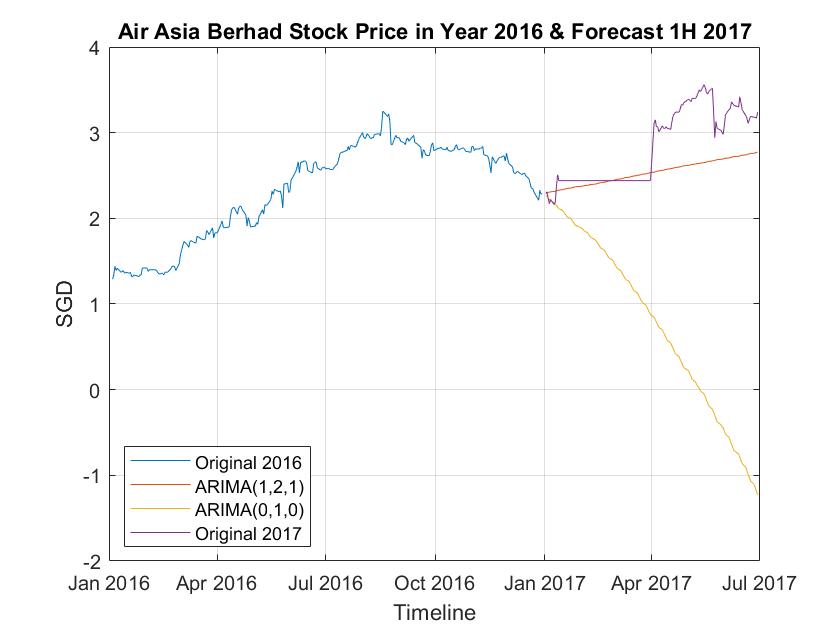

len=length(StockData_TimeTable_2017.Close);
ARIMA_CloseFinalForecast1 = forecast(ARIMA_Close1,len,'Y0',StockData_TimeTable_2016.Close);
ARIMA_CloseFinalForecast2 = forecast(ARIMA_CloseFinal,len,'Y0',StockData_TimeTable_2016.Close);

figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
plot(StockData_TimeTable_2017.Date,ARIMA_CloseFinalForecast1);
plot(StockData_TimeTable_2017.Date,ARIMA_CloseFinalForecast2);
plot(StockData_TimeTable_2017.Date,StockData_TimeTable_2017.Close);
title('Air Asia Berhad Stock Price in Year 2016 & Forecast 1H 2017');
ylabel('SGD');
xlabel('Timeline');
legend('Original 2016','ARIMA(1,2,1)','ARIMA(0,1,0)','Original 2017','Location','best');
grid on
hold off

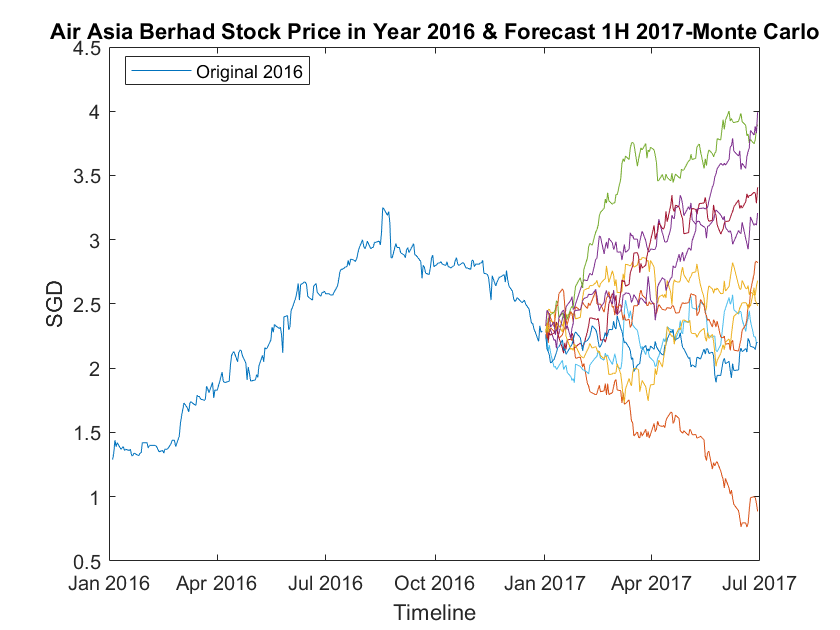

%Use Monte Carlo
[Montey,k]=simulate(ARIMA_Close1,len,'NumPath',10,'Y0',StockData_TimeTable_2016.Close);
figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
plot(StockData_TimeTable_2017.Date,Montey);
title('Air Asia Berhad Stock Price in Year 2016 & Forecast 1H 2017-Monte Carlo');
ylabel('SGD');
xlabel('Timeline');
legend('Original 2016','Location','best');

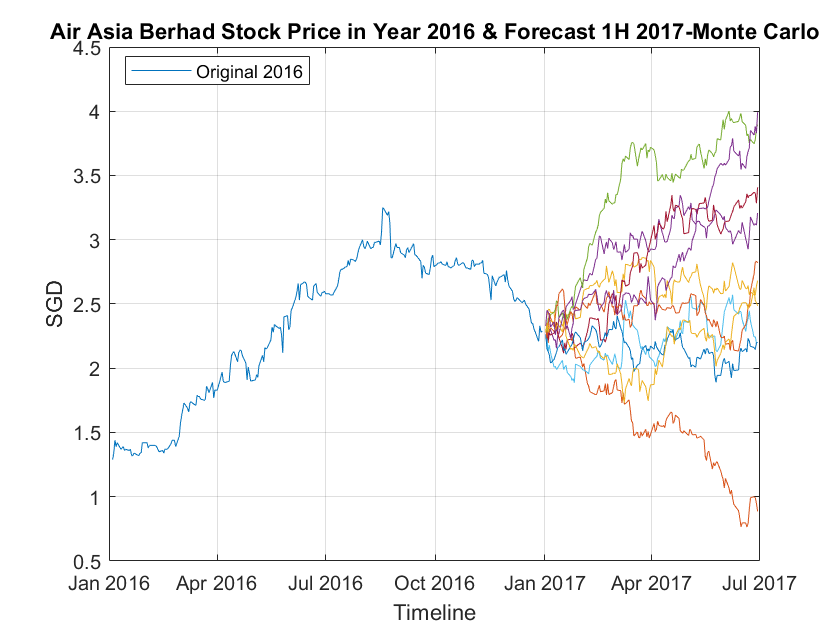

grid on
hold off

## Conclusion

In reality, stock price is highly relies on newly revealed information thus are inherently unpredictable for long term. As a result from there, time is really matter to help to do prediction in short-time, therefore, computational finance has raised the eyeball of many analysts or traders recently. 

With the advent of the digital computer, stock market prediction has since moved into the techonogical realm (machine learning & neural network).